clc;
clear;
close all;

## Esercizio 1

chieda in input un numero n e verifichi che sia intero e compreso tra 10 e 40. Dopo aver verificato che il numero inserito sia anche divisibile per 3, si costruisca e si visualizzi la matrice E di dimensione n × n fatta nel seguente modo:

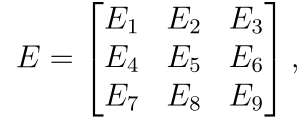

dove, assegnato a m il valore $n/3$ , ogni matrice $E_i \in R^{\;m\times m}$ contiene tutti valori uguali a i. Si costruiscano e si visualizzino, inoltre, il vettore z con tutti elementi uguali a 1 e il vettore $y = E \cdot  z$. Se il numero inserito n non dovesse verificare le condizioni richieste, dovrà esserne richiesto uno nuovo fino a quando non si ottiene un numero consentito.

flag = true;

while flag
    n = input("Inserisci un numero divisibile per 3 tra 10 e 40: ");
    if mod(n, 3) ~= 0 && n<10 && n>40
        disp("immetti un valore corretto");
    else
        flag = false;
    end
end

m = n/3;

E1 = ones(m);
E2 = 2 * ones(m);
E3 = 3 * ones(m);
E4 = 4 * ones(m);
E5 = 5 * ones(m);
E6 = 6 * ones(m);
E7 = 7 * ones(m);
E8 = 8 * ones(m);
E9 = 9 * ones(m);

E = [E1 E2 E3; E4 E5 E6; E7 E8 E9]

E =      1     1     1     1     2     2     2     2     3     3     3     3
     1     1     1     1     2     2     2     2     3     3     3     3
     1     1     1     1     2     2     2     2     3     3     3     3
     1     1     1     1     2     2     2     2     3     3     3     3
     4     4     4     4     5     5     5     5     6     6     6     6
     4     4     4     4     5     5     5     5     6     6     6     6
     4     4     4     4     5     5     5     5     6     6     6     6
     4     4     4     4     5     5     5     5     6     6     6     6
     7     7     7     7     8     8     8     8     9     9     9     9
     7     7     7     7     8     8     8     8     9     9     9     9
     7     7     7     7     8     8     8     8     9     9     9     9
     7     7     7     7     8     8     8     8     9     9     9     9



z = ones(n, 1)

y = E * z

y =     24
    24
    24
    24
    60
    60
    60
    60
    96
    96
    96
    96


clc;
clear;
close all;

## Esercizio 2

crei un test per la risoluzione di un sistema lineare Ax = b con il metodo iterativo di Jacobi. In particolare:

• generare le matrici dei coefficienti del sistema di dimensione crescente da 10 a 100 con passo 10, contenenti numeri pseudo-casuali reali compresi tra −5 e 5;

• rendere la matrice diagonalmente dominante, imporre una soluzione nota x di elementi uguali a 1 e calcolare il corrispondente termine noto b;

• trovare l’approssimazione x1 della soluzione del sistema utilizzando il metodo iterativo di Jacobi impostando una tolleranza τ = 10e−5 e un numero massimo di iterazioni kmax = 100;

• infine, calcoli e visualizzi una tabella in cui compaiono la dimensione della matrice e l’errore relativo tra la soluzione vera x e quella ottenuta x1 .

iMin = -5;
iMax = 5;
k = 1;
tau = 10e-5;
kmax = 100;

for i = 10 : 10 : 100
    A = (iMax-iMin) * rand(i) + iMin;

Rendo la mareice diagonalmente dominante

    A = A - diag(diag(A));
    s = sum(abs(A));           %Il vettore contiene la somma di tutti i valori assoluti della colonna
    s = s + 0.1;
    A = A + diag(s);

impongo la soluzione x e calcolo b = A*x

    x = ones(i, 1);
    b = A*x;

Trovo la soluzione x1 con jacobi

    [x1, ki] = jacobi(A, b, tau, kmax);

Calcolo l'errore relativo

    errRel(k) = norm(x - x1) / norm(x);
    k = k+1;
end

Mostro i dati riportati in tabella:

dim = 10 : 10 : 100;
t = table(dim', errRel', 'VariableNames', {'Dimensione', 'Errore Relativo tra x e x1'});
disp(t);

    Dimensione    Errore Relativo tra x e x1
    __________    __________________________

        10                7.0337e-06        
        20                1.6964e-06        
        30                1.1046e-06        
        40                1.0726e-06        
        50                4.4178e-07        
        60                1.3408e-06        
        70                8.9028e-07        
        80                7.1481e-07        
        90                3.6784e-07        
       100                4.1051e-07        



clc;
clear;
close all;

## Esercizio 3

implementi un test per l’approssimazione della radice positiva dell’equazione nonlineare

utilizzando il metodo di Newton, con punto iniziale x0 = 1, e con il metodo di bisezione, partendo dall’intervallo [0, 4]. Per entrambi i metodi, impostare una tolleranza τ = 10e−5 e un numero massimo di iterazioni kmax = 100. Infine si stampi, sullo stesso sistema di assi cartesiani, il grafico della funzione f (x) e le due approssimazioni ottenute. Il grafico dovrà essere corredato da un titolo e una legenda.

Le due funzioni

• [xn, kn] = newton(f,fder,x0 ,τ ,kmax)

• [xb, kb] = bisezione(f,a,b,τ ,kmax)

dovranno essere allegate alla fine dello script.

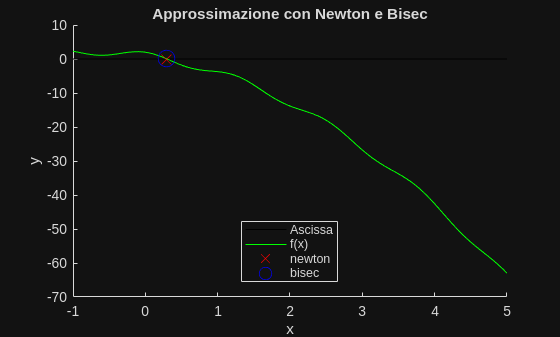

x0 = 1;
tau = 10e-5;
kmax = 100;
a = 0;
b = 4;

f = @(x) cos(5.*x) - 2.*x.*x - 3.*x + 1;
fder = @(x) -5*sin(5.*x) - 4.*x - 3;

x = linspace(-1, 5);

[xn, kn] = newton(f, fder, x0, tau, kmax);
[xb, kb] = bisezione(f, a, b, tau, kmax);

figure;
hold on;
title("Approssimazione con Newton e Bisec");
xlabel("x");
ylabel("y");

plot(x, zeros(size(x)), "-k", "DisplayName", "Ascissa");
plot(x, f(x), "-g", "DisplayName", "f(x)");
plot(xn, f(xn), "xr", "DisplayName", "newton", "MarkerSize", 10);
plot(xb, f(xb), "ob", "DisplayName", "bisec", "MarkerSize", 12);

legend("Location","best")
hold off;

function [x, k] = jacobi(A, b, tau, k_max)

    % jacobi: metodo per trovare un'approssimazione delle radici tramite 
    % iterazioni successive di un sistema di equazioni lineari
    %   [x, k] = jacobi(A, b, x0, tau, k_max) restituisce le soluzioni
    %   della matrice e il numero di iterazioni effettuate.


    % tau e k_max sono le condizioni d'arresto:
        % tau = tolleranza
        % k_max = iterazioni massime
    
    % Controllo che la matrice non sia singolare
    if (abs(det(A)) < 1e-12)
        error("Il sistema può non ammettere soluzioni");
    end
    
    
    x0 = zeros(size(A, 1), 1);
    x0(1) = 1;
    
    % A = D - E - F
    
    % diag() restituisce un vettore, quindi diag() su di esso mi rende una 
    % matrice con tutti 0 tranne la diagonale, che avrà i valori del
    % vettore
    D = diag(diag(A));
    
    %E = (tril(A) - D) * -1;
    E = -tril(A, -1);
    
    F = -triu(A, 1);
    
    %Bj = D^-1 * (E + F);
    Bj = D\(E + F);
    
    %fj = D^-1 * b;
    fj = D\b;
    
    % Un MLS1 converge quando il rho della matrice di iterazione è < 1
    rho = abs(eigs(Bj, 1, 'largestabs')); % anche con largestabs restituisce l'autovalore col suo segno originario
    
    if (rho >= 1)
        error("Il metodo non converge");
    end
    

    % Inizializzazione variabili
    x_old = x0;
    flag = true;
    k = 1;

    while (flag)
        % Condizione di stop per massimo numero di iterazioni
        if (k >= k_max)
            warning("k_max è stato raggiunto");
            break;
        end
    
        x_new = Bj * x_old + fj;
    
        % Condizione di stop per soluzioni accettabili, cioè abbastanza
        % vicine alla soluzione reale
        if (norm(x_new - x_old) < tau)
            flag = false;
        else
            % Aggiornamento variabili per l'iterazione successiva
            x_old = x_new;
            k = k + 1;
        end
    end
    
    x = x_new;
end

function [xn, kn] = newton(f, fder, x0, tau, kmax)

    % newton: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0
    %   [xn, kn] = newton(f, fder, x0, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.


    % Inizializzo xn
    xn = x0;

    % Se il punto passato è già soluzione lo restituisco
    if(abs(f(x0)) < tau)
        kn = 0;
        return;
    end

    % Inizio algoritmo iterativo da k a kmax
    for kn = 1 : kmax
        
        f1 = fder(x0);

        if(abs(f1) < tau)
            error("La derivata tende a 0: cambia il valore x0");
        end

        % Formula Newton
        xn = x0 - f(x0) / f1;

        % Condizioni di arresto: se la soluzione non è variata
        % significativamente dall'iterazione precedente o se l'immagine
        % risulta abbastanza vicina a 0
        if abs(f(xn)) < tau || abs(xn - x0) < tau * abs(x0)
            return;
        end

        % Aggiornamento variabili
        x0 = xn;

    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    warning("Iterazioni massime raggiunte");

end

function [xb, kb] = bisezione(f, a, b, tau, kmax)
    
    % bisezione: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0 
    %   [xb, kb] = bisezione(f, a, b, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.


    % Inizializzo la variabile fa con f(a) per non doverla calcolare più
    % volte
    fa = f(a);

    % Controllo che nell'intervallo sia contenuta la radice che cerco
    if(fa * f(b) > 0)
        error("Nessuna radice nell'intervallo [%g, %g]", a, b);
    end


    % Inizio algoritmo iterativo da k a kmax
    for kb = 1 : kmax
       
        % Formula bisezione
        xb = (a + b) / 2;
        
        % Aggiorno l'immagine della x trovata per non doverla calcolare più
        % volte
        fxb = f(xb);

        % Controllo la positività dell'immagine trovata e aggiorno
        % l'intervallo
        if(fa * fxb < 0)
            b = xb;
        else
            a = xb;
            fa = fxb;
        end
        
        % Condizioni di arresto
        if abs(fxb) < tau
            return;
        end

    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    warning("Iterazioni massime raggiunte");

end